Our reference circuit input circuit is shown below:

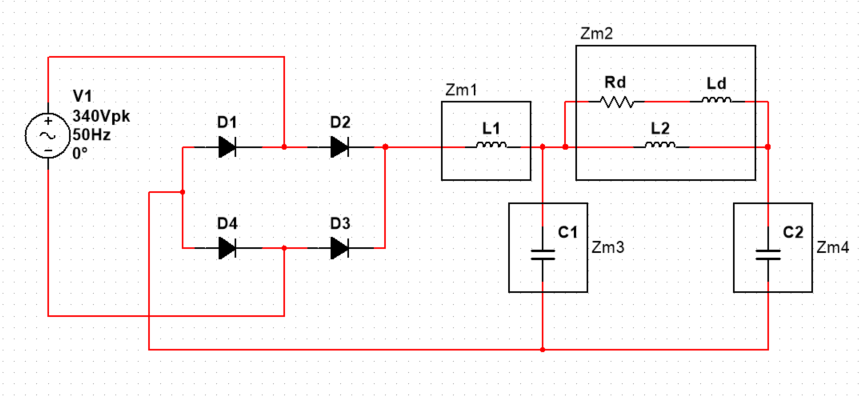

In order to supply the flyback with stable DC to switch, we need to design a cost-effective, and compact filter solution. The output put of our flyback will have significantly less ripple than the input, but it is still important to keep the ripple to a minimum on our input filtering. Our target output ripple is 5mVpp.

To design the filter circuit, we are using the [TI SNVA548](https://www.ti.com/lit/an/snva538/snva538.pdf) reference document on the subject.

As our goal is to design a low-cost and compact filter solution, we will be using the multi-stage filter outlined in the document.

The following gives the transfer function of the multi-stage filter.

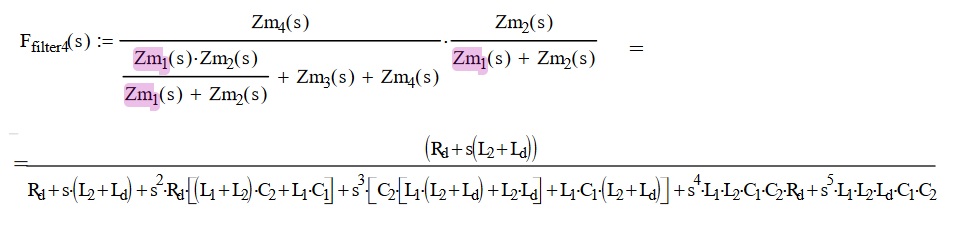 

The two-stage filter was optimized with the following ratios in the literature: 

clc; clear;

Lf = 1e-3;
Cf = 300e-6;

C1 = Cf/4;
C2 = 4*C1;
L1 = Lf/4;
L2 = 7*L1;
Ld = L1/8;
Rd = sqrt(L1/(C2));

num2sip(C1)

ans = '75 µ'

num2sip(C2)

ans = '300 µ'

num2sip(L1)

ans = '25 m'

num2sip(L2)

ans = '175 m'

num2sip(Ld)

ans = '3.125 m'

num2sip(Rd)

ans = '9.1287 '


%Transfer Function
numerator = [L2+Ld,Rd];
denominator = [L1*L2*Ld*C1*C2, L1*L2*C1*C2*Rd, C2*(L1*(L2+Ld)+L2*Ld), Rd*((L1+L2)*C2+L1*C1), L2+Ld,Rd];

sys = tf(numerator,denominator)

sys =
 
                                 0.1781 s + 9.129
  ------------------------------------------------------------------------------
  3.076e-13 s^5 + 8.986e-10 s^4 + 1.5e-06 s^3 + 0.0005648 s^2 + 0.1781 s + 9.129
 
Continuous-time transfer function.



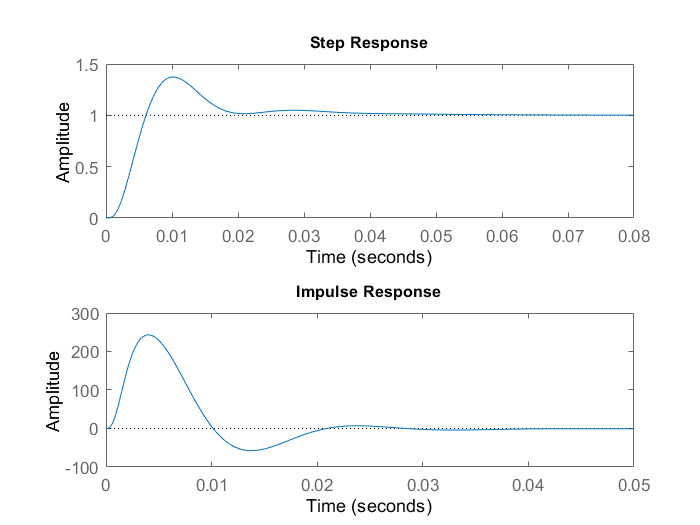

figure(1)
subplot(2,1,1)
step(sys)
subplot(2,1,2)
impulse(sys)

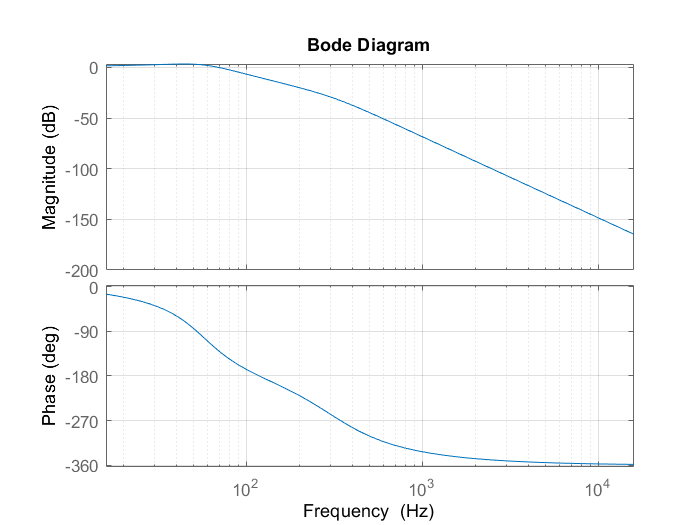

figure(2)
p = bodeoptions('cstprefs');
p.FreqUnits = 'Hz';
bode(sys,p,{100,100000})
grid on